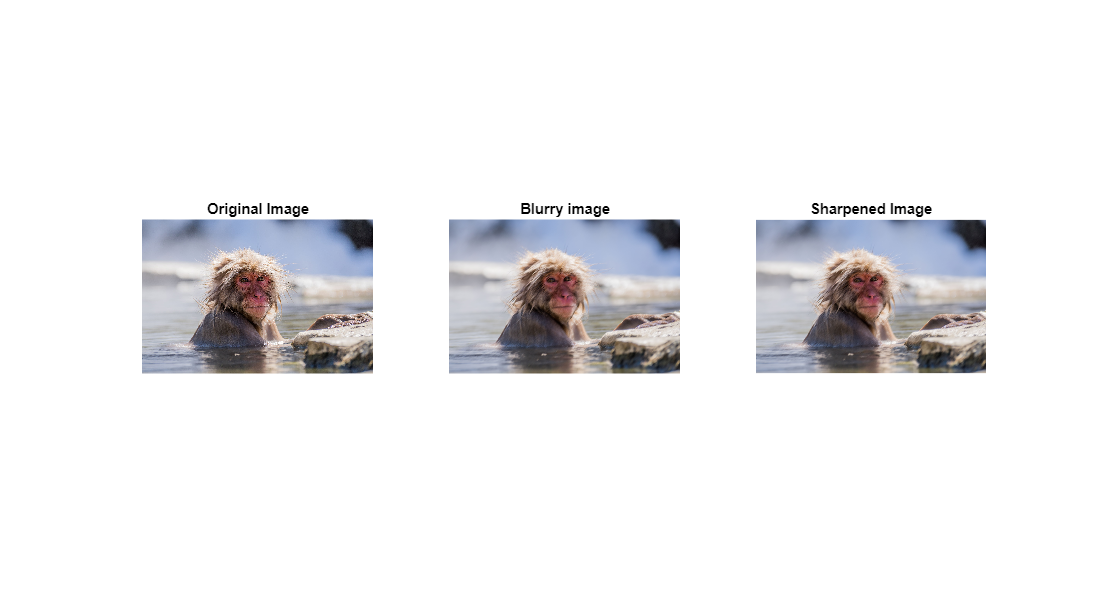

 
[fname, fpath] = uigetfile( ...
    {'*.jpg;*.jpeg;*.png'}, ...
    'Select file to open' ...
);

im = imread([fpath, fname]);
H = fspecial("motion", 20, 45);
motionBlur = imfilter(im, H, "replicate");
sharpenedIm = imsharpen(motionBlur);

f1 = figure(Name="Image sharpening");
f1.Position = [0 0 1920 1080];
axis off;
subplot(1, 3, 1);
imshow(im);
title("Original Image");
subplot(1, 3, 2);
imshow(motionBlur);
title("Blurry image");
subplot(1, 3, 3);
imshow(sharpenedIm);
title("Sharpened Image");